障已知的实验,

clear
clc
 
ulogOBJ = ulogreader("log_2_2022-4-25-23-25-24.ulg");
msg = readTopicMsgs(ulogOBJ);

## known_logger

更换log文件后需要修改下面的数值，找到msg中对应的known_logger的序号是多少。

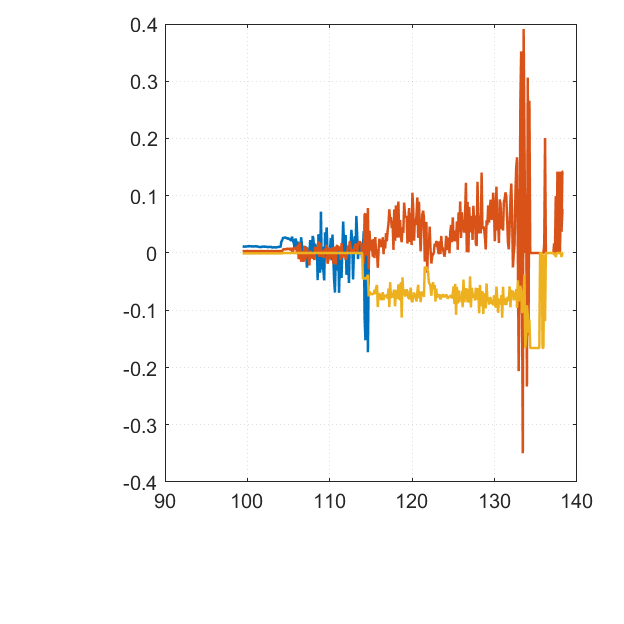

 
% 获取known_logger数据
known_logger = msg.TopicMessages{findtopic(msg.TopicNames, 'known_logger')};
% 生成相对时间
log_time = known_logger.timestamp;
time = seconds(log_time);
[time_size,~] = size(time);

% 读取数据
tDes = known_logger.tdes;
iter = known_logger.iter;

% 画图
figure(10)
clf
c = (0.0166);
l = (0.125);
M = ([ 1          1          1         1;
      -0.7071*l  -0.7071*l   0.7071*l  0.7071*l;
       0.7071*l  -0.7071*l  -0.7071*l  0.7071*l;
       c         -c          c        -c]);
for i=1:time_size
    vAct(:,i) = M*tDes(i,:)';
end

plot(time,vAct(2:4,:))



s = figure(11);
% s.Position(4) = 15;
clf
subplot(5,1,1)
plot(time,tDes(:,1)/5*8)
hold on
plot(time,tDes(:,3)/5*8)
hold on
plot(time,tDes(:,4)/5*8,'--')
hold on
plot(time,tDes(:,2)/5*8,'--')
ylabel('Rotor Force(N)','Interpreter',"latex")
legend('#1','#2','#3','#4','Location',"northoutside",'Orientation',"horizontal")

subplot(5,1,2)
plot(time, iter,'--o','LineWidth',0.5)
legend('Iterations')
ylim([0,10])

## vehicle_attitude

vehicle_attitude = msg.TopicMessages{findtopic(msg.TopicNames, 'vehicle_attitude')};
% 生成相对时间
time = seconds(vehicle_attitude.timestamp);

% 获取数据
[size_time,~] = size(time);
quate = vehicle_attitude.q;
angle = quat2dcm(quate);

primary_axis = zeros(size_time,3);
for i=1:size_time
    primary_axis(i,:) = angle(:,:,i)*[0,0,1]';
end

subplot(5,1,3)
plot(time,primary_axis(:,1))
hold on
plot(time,primary_axis(:,2))
hold on
plot(time,primary_axis(:,3))
ylabel('$\mathbf{n}_3$','Interpreter',"latex")
legend('$h_1$','$h_2$','$h_3$','Orientation',"horizontal",'Interpreter',"latex")

## sensor_combined

sensor_combined = msg.TopicMessages{findtopic(msg.TopicNames, 'sensor_combined')};
% 生成相对时间
time = seconds(sensor_combined.timestamp);

% 获取数据 
gyro = sensor_combined.gyro_rad;

subplot(5,1,4)
plot(time, gyro)
legend('p','q','r','Orientation',"horizontal")
ylabel('(rad/s)','Interpreter',"latex")

## input_rc

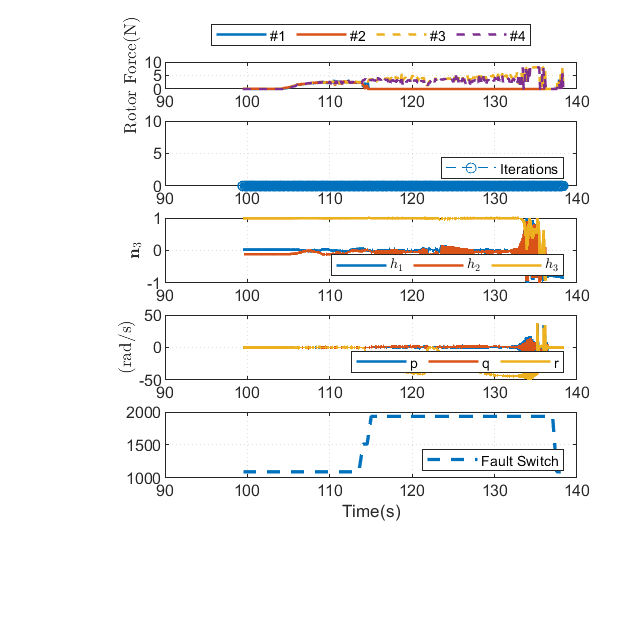

input_rc = msg.TopicMessages{findtopic(msg.TopicNames, 'input_rc')};
% 生成相对时间
log_time = input_rc.timestamp;
time = seconds(log_time);
[sample_count,~] = size(log_time);
% 获取数据
rc = input_rc.values;

subplot(5,1,5)
% plot(time,rc(:,1),'LineWidth',1)
% hold on
% plot(time,rc(:,2),'LineWidth',1)
% hold on
% plot(time,rc(:,3),'--')
% hold on
% plot(time,rc(:,4),'--')
% hold on
% plot(time,rc(:,5),'--')
% hold on
plot(time,rc(:,6),'--','LineWidth',2)
legend('Fault Switch','Location',"best",'Orientation',"horizontal")
xlabel('Time(s)')